descarga de datos


datos = readtable('datos_personas.xlsx', 'VariableNamingRule','preserve')

datos = 25000×4 table
    Index    Altura(m)    Peso(kg)     IMC  
    _____    _________    ________    ______

      1       1.6709       51.253     18.358
      2       1.8165        61.91     18.763
      3       1.7627       69.412     22.339
      4       1.7327       64.562     21.505
      5       1.7218       65.452     22.078
      6       1.7449       55.929     18.369
      7        1.773       64.181     20.417
      8       1.7784       61.898     19.572
      9       1.7247       50.971     17.135
     10       1.6963       54.734     19.022
     11       1.6888       57.811      20.27
     12       1.7176       51.774     17.549
     13       1.7349       56.976      18.93
     14       1.7048       55.548     19.113
     15       1.7343       52.656     17.506
     16       1.8057       63.502     19.475


grafico tres variables


alturas = datos.("Altura(m)");
pesos = datos.("Peso(kg)");
imcs = datos.IMC;

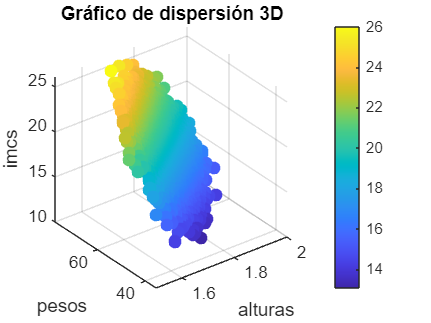


figure;
scatter3(alturas, pesos, imcs, 50, imcs, 'filled'); 
grid on;
xlabel('alturas');
ylabel('pesos');
zlabel('imcs');
title('Gráfico de dispersión 3D');
colorbar; 


% reducción a una variable entre altura y peso
base_altura_peso = [alturas, pesos];
[coeff, score, latent] = pca(base_altura_peso); % score contiene las componentes principales
primera_componente = score(:, 1); % primera
segunda_componente = score(:,2); %segunda
varianza_total = sum(latent)

varianza_total = 27.9790


proporcion_varianza = latent / sum(latent)  % Proporciones de varianza para componente 1 y 2 

proporcion_varianza =     0.9999
    0.0001




%la segunda componente es irrelevante



% Calcular correlaciones originales y transformadas
correlacion_peso_altura = corr(alturas,pesos);
correlacion_peso_imc = corr(pesos, imcs);
correlacion_altura_imc = corr(alturas, imcs);
correlacion_promedio = (correlacion_peso_altura+correlacion_peso_imc+correlacion_altura_imc)/3

correlacion_promedio = 0.3923


correlacion_transformada = corr(primera_componente, imcs)

correlacion_transformada = 0.7955


%correlacion al aplicar apc al componente generado con peso y altura con
%imcs

base_componente_imcs = [primera_componente, imcs];
[coeff2, score2, latent2] = pca(base_componente_imcs)

coeff2 =     0.9723   -0.2339
    0.2339    0.9723


score2 =    -6.4381    0.5575
    4.0186   -1.5417
   12.1489    0.1807
    7.2386    0.5038
    8.2377    0.8529
   -1.8884   -0.5254
    6.6138   -0.4639
    4.1967   -0.7522
   -6.9974   -0.5654
   -2.8979    0.3895


latent2 =    29.5482
    0.8375



varianza_total2 = sum(latent2)

varianza_total2 = 30.3856


proporcion_varianza2 = latent2 / varianza_total2 

proporcion_varianza2 =     0.9724
    0.0276



% comparar PCA entre las tres variables y solo altura/peso

datos_tres_variables = [alturas, pesos, imcs];
[coeff_3, score_3, latent_3] = pca(datos_tres_variables);

%variabilidades
varianza_total2 = sum(latent_3)

varianza_total2 = 30.3874


proporcion_varianza_nuevo = latent_3 / sum(latent_3)

proporcion_varianza_nuevo =     0.9724
    0.0276
    0.0000



%la tercera componente no explica nada directamente, y la segunda un 2.76%

%filtrar valores extremos y repetir ACP

% Criterio de filtrado: rango intercuartílico en alturas


% Ordenar la base en función de la altura
base_ordenada_por_altura = sortrows(datos, 'Altura(m)');


% Definir el filtro basado en altura para la base ordenada
lim_inf_altura = quantile(base_ordenada_por_altura.("Altura(m)"), 0.05);
lim_sup_altura = quantile(base_ordenada_por_altura.("Altura(m)"), 0.95);

% Crear el filtro
filtro_altura = (base_ordenada_por_altura.("Altura(m)")  >= lim_inf_altura) & (base_ordenada_por_altura.("Altura(m)") <= lim_sup_altura);

% Aplicar el filtro a la base ordenada
base_filtrada_altura = base_ordenada_por_altura(filtro_altura, :);

% tamannos antes y depeues
disp('Tamaño de la base original:');

Tamaño de la base original:


disp(height(datos));

       25000



disp('Tamaño de la base filtrada:');

Tamaño de la base filtrada:


disp(height(base_filtrada_altura));

       22500



Correlaciones originales con IMC después del filtrado:


   -0.1206
    0.7970



Correlación de la primera componente principal con IMC después del filtrado:


    0.7970



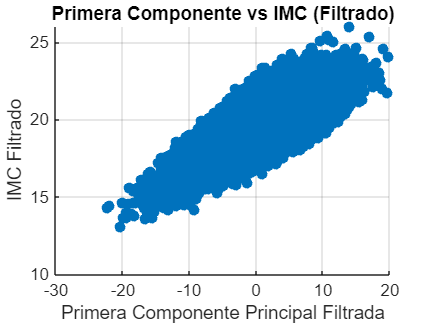


% análisis ACP usando la base filtrada
datos_filtrados_altura = [base_filtrada_altura.("Altura(m)"), base_filtrada_peso.("Peso(kg)")];

[coeff_filtr_alt, score_filtr_alt, latent_filtr_alt] = pca(datos_filtrados_altura);

varianzas_filtro_alt = latent_filtr_alt/sum(latent_filtr_alt)
%correlaciones con IMC después del filtrado
correlaciones_filtradas_alt = corr([base_filtrada_altura.("Altura(m)"), base_filtrada_altura.("Peso(kg)")], base_filtrada_altura.IMC)


% Gráficos
figure;
scatter(score_filtr_alt(:, 1), base_filtrada_altura.IMC, 'filled');
xlabel('Primera Componente Principal Filtrada');
ylabel('IMC Filtrado');
title('Primera Componente vs IMC (Filtrado)');
grid on;



% Criterio de filtrado: rango intercuartílico en pesos


% Ordenar la base en función del peso
base_ordenada_por_peso = sortrows(datos, 'Peso(kg)');

Tamaño de la base original:


       25000



% Definir el filtro basado en peso para la base ordenada

Tamaño de la base filtrada:


lim_inf_peso = quantile(base_ordenada_por_peso.("Peso(kg)"), 0.05);

       22500



lim_sup_peso = quantile(base_ordenada_por_peso.("Peso(kg)"), 0.95);

% Crear el filtro 
filtro_peso = (base_ordenada_por_peso.("Peso(kg)")  >= lim_inf_peso) & (base_ordenada_por_peso.("Peso(kg)") <= lim_sup_peso);

% Aplicar el filtro a la base ordenada
base_filtrada_peso = base_ordenada_por_peso(filtro_peso, :);

varianzas_filtro_peso =     0.9999
    0.0001



%tamaños de la base antes y después del filtrado

correlaciones_filtradas_peso =    -0.3336
    0.7154


disp('Tamaño de la base original:');
disp(height(datos));
disp('Tamaño de la base filtrada:');
disp(height(base_filtrada_peso));

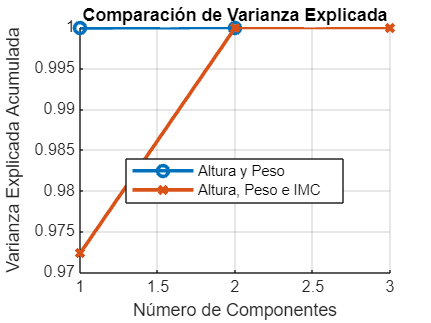


% continuar con el análisis ACP usando la base filtrada
datos_filtrados_peso = [base_filtrada_peso.("Altura(m)"), base_filtrada_peso.("Peso(kg)")];
[coeff_filtr_peso, score_filtr_peso, latent_filtr_peso] = pca(datos_filtrados_peso);


varianzas_filtro_peso = latent_filtr_peso/sum(latent_filtr_peso)
% Calcular correlaciones con IMC después del filtrado
correlaciones_filtradas_peso = corr([base_filtrada_peso.("Altura(m)"), base_filtrada_peso.("Peso(kg)")], base_filtrada_peso.IMC)


% Gráficos
figure;
scatter(score_filtr_peso(:, 1), base_filtrada_peso.IMC, 'filled');
xlabel('Primera Componente Principal Filtrada');
ylabel('IMC Filtrado');
title('Primera Componente vs IMC (Filtrado)');
grid on;


% Criterio de filtrado: rango intercuartílico en imcs

% Ordenar la base en función del imc
base_ordenada_por_imc = sortrows(datos, 'IMC');


% Definir el filtro basado en altura para la base ordenada
lim_inf_imc = quantile(base_ordenada_por_imc.("IMC"), 0.05);

Tamaño de la base original:


lim_sup_imc = quantile(base_ordenada_por_imc.("IMC"), 0.95);

       25000



Tamaño de la base filtrada:


% Crear el filtro

       22500



filtro_imc = (base_ordenada_por_imc.("IMC")  >= lim_inf_imc) & (base_ordenada_por_imc.("IMC") <= lim_sup_imc);

% Aplicar el filtro a la base ordenada
base_filtrada_imc = base_ordenada_por_imc(filtro_imc, :);

% tamannos antes y depeues
disp('Tamaño de la base original:');
disp(height(datos));
disp('Tamaño de la base filtrada:');
disp(height(base_filtrada_imc));

Correlaciones originales con IMC después del filtrado:


   -0.1209
    0.7938



Correlación de la primera componente principal con IMC después del filtrado:


    0.7937



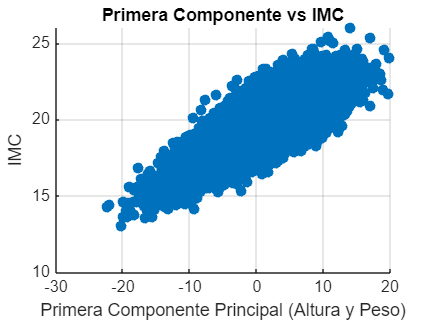


% análisis ACP usando la base filtrada
datos_filtrados_imc = [base_filtrada_imc.("Altura(m)"), base_filtrada_peso.("Peso(kg)")];

[coeff_filtr_imc, score_filtr_imc, latent_filtr_imc] = pca(datos_filtrados_imc);

varianzas_filtro_imc = latent_filtr_imc/sum(latent_filtr_imc)
%correlaciones con IMC después del filtrado
correlaciones_filtradas_imc = corr([base_filtrada_imc.("Altura(m)"), base_filtrada_imc.("Peso(kg)")], base_filtrada_imc.IMC)


% Gráficos
figure;
scatter(score_filtr_imc(:, 1), base_filtrada_imc.IMC, 'filled');
xlabel('Primera Componente Principal Filtrada');
ylabel('IMC Filtrado');
title('Primera Componente vs IMC (Filtrado)');
grid on;